# Processing Radar Data to Output SNR

Preperation of data

inputstructure = active; % define your data input structure
inputstructure.name = "Active"; % define your data input name
inputdata = inputstructure.range_doppler_slices;  
signal=zeros(1,length(inputdata));
noise=zeros(1,length(inputdata));
SNR=zeros(1,length(inputdata));
slices_range_doppler = createArrays(length(inputdata), size(inputdata{1,1}));
for i=1:length(inputdata)
    [signal(i),noise(i),SNR(i),slices_range_doppler{i},signal_idx(i)]=slice_SNR(active.range_doppler_slices{1,i});
end    

1) Generate Range-Doppler plots for 3 slices within the Active data

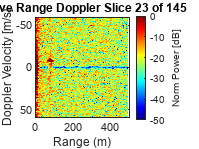

x = inputstructure.range_axis; % x_axis
y = inputstructure.doppler_velocity_axis; % y_axis
dynamic_range = +50; % user defined dynamic range to maximise visualisation
max_range = 500; % user defined max range to maximise visualisation
max_doppler = 60; % user defined max doppler to maximise visualisation
k = 23; % define which slice number you want to visalise

figure_title = (inputstructure.name + ' Range Doppler Slice ' + k...
    + ' of ' + length(inputdata));
fig = figure;
imagesc(x,y,slices_range_doppler{1, k},[-dynamic_range 0])
title(figure_title);
ylabel('Doppler Velocity [m/s]');
xlabel('Range (m)') ;  
c = colorbar;
c.Label.String='Norm Power [dB]';
ylim([-max_doppler max_doppler]); % Doppler Limit
xlim([-inf max_range]);   % Range Limit
colormap jet;



%plot(x,y,'--gs'

[idx_x, idx_y] = ind2sub(size(slices_range_doppler{1,3}),signal_idx(3))

idx_x = 243

idx_y = 2

plot(idx_x, idx_y,"m" )
hold off
%fig = figure;

Save Range Doppler Figure

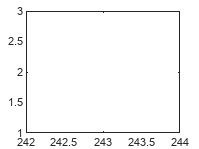

exp_dir = exp_dir; % user defined export directory
fig_name = exp_dir + figure_title;
savefig(figure_title)
saveas(fig, fig_name, 'png')

2) Quantify Signal and Noise

3) Define SNR in dB for all slices

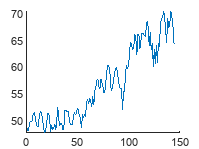

% SNR over Slices
figure
hold on
plot(1:145, SNR)


[idx_x, idx_y] = ind2sub(size(slices_range_doppler{1,3}),signal_idx(3))

idx_x = 243

idx_y = 2

4) Plot SNR against Time for all slices of Active data

5) Inject Noise to the Active data (+10dB)